clear;
img = imread("IMG_9528.JPG")

img = 4032×2268×3 uint8 array
img(:,:,1) =

    78    78    78    78    78    78    78    78    76    77    77    77    78    78    78    78    79    79    79    79    79    79    78    78    77    78    78    78    78    78    79    79    78    78    78    78    78    78    78    78    79    79    79    79    79    79    79    79    79    79    78    78    78    78    79    79    78    79    79    79    80    79    79    79    79    79    79    79    79    79    80    81    81    80    78    78    77    77    78    79    80    80    80    80    80    79    79    79    79    79    79    79    78    78    78    78    76    77    77    77    77    78    79    80    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    78    79    79    79    78    78    78    78    78    77    77    76    76    77    77    78    78    78    78    78    78    77    77    77    76    76    75    75    75    75    75    75    75    75    75    75    75    75    74  



[height, width, ~] = size(img);

boxSize = 100;

% Number of full boxes
numOfBoxesHeight = floor(height / boxSize)

numOfBoxesHeight = 40

numOfBoxesWidth = floor(width / boxSize)

numOfBoxesWidth = 22


% Remainder after division
remHeight = mod(width, boxSize)

remHeight = 68

remWidth = mod(height, boxSize)

remWidth = 32

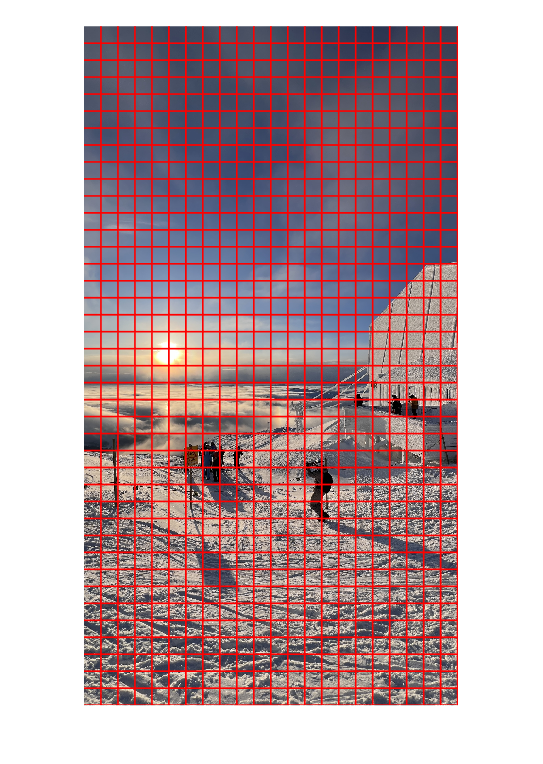


% Crop image, only keep full boxes

croppedImg = img(1:numOfBoxesHeight*boxSize, 1:numOfBoxesWidth*boxSize,:);

figure;
imshow(croppedImg);

hold on;

% Draw the grid lines
for i = 1:numOfBoxesWidth
    x = i * boxSize;
    line([x, x], [0, numOfBoxesHeight * boxSize], 'Color', 'r', 'LineWidth', 1);
end

for j = 1:numOfBoxesHeight
    y = j * boxSize;
    line([0, numOfBoxesWidth * boxSize], [y, y], 'Color', 'r', 'LineWidth', 1);
end

hold off;


% Initialize matrix to store average RGB & Lab values
avgColors = zeros(numOfBoxesHeight, numOfBoxesWidth, 3);
avgLABColors = zeros(numOfBoxesHeight, numOfBoxesWidth, 3);

% Loop through each box
for i = 1:numOfBoxesHeight
    for j = 1:numOfBoxesWidth
        
        % Get current box
        box = croppedImg((i-1)*boxSize+1:i*boxSize, (j-1)*boxSize+1:j*boxSize, :);

        % Calculate average RGB values for the box
        avgR = mean(box(:,:,1), 'all');
        avgG = mean(box(:,:,2), 'all');
        avgB = mean(box(:,:,3), 'all');

        % Store the average RGB values
        avgColors(i, j, :) = [avgR, avgG, avgB];

        % Convert RGB to LAB (normalize RGB to [0, 1] range first)
        labColor = rgb2lab(cat(3, avgR/255, avgG/255, avgB/255));

        % Store the LAB values
        avgLABColors(i, j, :) = labColor;
    end
end

% Print the average color for the first box as an example
fprintf('Average RGB for box (1,1): [%.2f, %.2f, %.2f]\n', avgLABColors(1, 1, 1), avgLABColors(1, 1, 2), avgLABColors(1, 1, 3));

Average RGB for box (1,1): [36.33, 1.49, -10.02]



fprintf('Average RGB for box (10,10): [%.2f, %.2f, %.2f]\n', avgLABColors(10, 10, 1), avgLABColors(10, 10, 2), avgLABColors(10, 10, 3));

Average RGB for box (10,10): [34.32, 3.57, -22.62]


testMatrix = {
    'image1.jpg', [labColor(:,:,1), labColor(:,:,2), labColor(:,:,3)]; 
    'image2.jpg', [36, 1.49, -10]; 
    'image3.jpg', [36.33, 1.49, 10.02]
}

testMatrix = 3×2 cell array
    {'image1.jpg'}    {[ 52.0765 1.1442 0.3928]}
    {'image2.jpg'}    {[         36 1.4900 -10]}
    {'image3.jpg'}    {[36.3300 1.4900 10.0200]}



closestImages = findClosestImage(avgLABColors, testMatrix);
fprintf('Closest image for box (1,1): %s\n', closestImages{1, 1});

Closest image for box (1,1): image2.jpg


% Match pictures with box

% Define folder path
folderPath = "../pics";

% Initialize the new mosaic image
mosaicImg = uint8(zeros(numOfBoxesHeight * boxSize, numOfBoxesWidth * boxSize, 3));

% Loop through each box to place the closest matching image
for i = 1:numOfBoxesHeight
    for j = 1:numOfBoxesWidth
        
        % Get the name of the closest matching image
        closestImageName = closestImages{i, j};
        imagePath = fullfile(folderPath, closestImageName);
        
        if isfile(imagePath)
            % Read and resize the image to fit the box size
            closestImg = imread(imagePath);
            closestImg = imresize(closestImg, [boxSize, boxSize]);

            % Place the resized image in the correct position
            yRange = (i-1)*boxSize+1 : i*boxSize;
            xRange = (j-1)*boxSize+1 : j*boxSize;

            mosaicImg(yRange, xRange, :) = closestImg;
        else
            warning('Image not found: %s', imagePath);
        end
    end
end

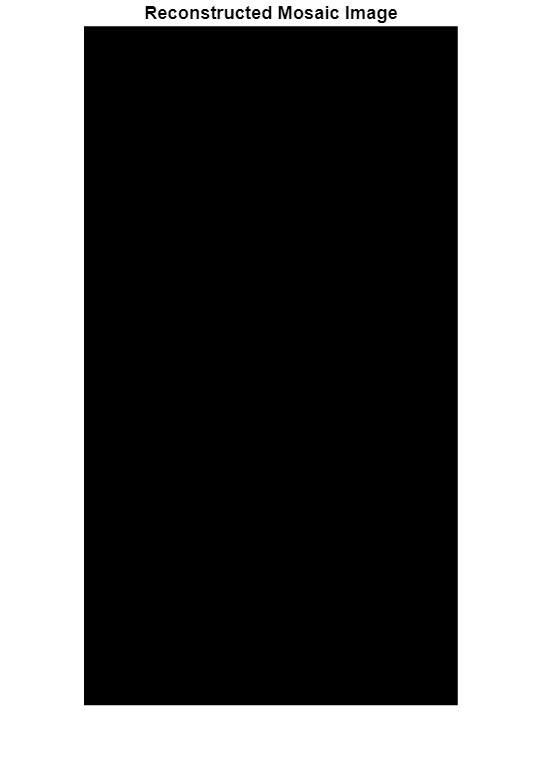


% Show the final mosaic image
figure;
imshow(mosaicImg);
title('Reconstructed Mosaic Image');